**Comparison between MUSIC, ROOT MUSIC, ESPRIT and MVDR as DOA estimation algorithms for two arriving signals **

configure a ULA and choose two angles of arrival for the two signlas. number of snapshots, noise and signal power are also configurable

ula = phased.ULA('NumElements',10,'ElementSpacing',0.5);
ang1 = [40; 0];          % First signal
ang2 = [30; 0];         % Second signal
angs = [ang1 ang2];

c = physconst('LightSpeed');
fc = 300e6;              % Operating frequency
lambda = c/fc;
pos = getElementPosition(ula)/lambda;
nPower = 0.01;% noise power, uncorrelated
Nsamp = 1000;%number of snapshots
spower = 1;%signal power in watts, uncorrelated signals
rs = rng(2007);

signal = sensorsig(pos,Nsamp,angs,nPower,spower);
broadside_angle = az2broadside(angs(1,:),angs(2,:))

broadside_angle =    40.0000   30.0000


**MVDR results:**

mvdrspatialspect = phased.MVDREstimator('SensorArray',ula,...
        'OperatingFrequency',fc,'ScanAngles',-90:90,...
        'DOAOutputPort',true,'NumSignals',2);
[~,DOA_MVDR_estimation] = mvdrspatialspect(signal)

DOA_MVDR_estimation =     40    30


**MUSIC results:**

musicspatialspect = phased.MUSICEstimator('SensorArray',ula,...
        'OperatingFrequency',fc,'ScanAngles',-90:90,...
        'DOAOutputPort',true,'NumSignalsSource','Property','NumSignals',2);
[~,DOA_MUSIC_estimation] = musicspatialspect(signal) 

DOA_MUSIC_estimation =     40    30


**ESPRIT results:**

espritspatialspect = phased.ESPRITEstimator('SensorArray',ula,...
       'OperatingFrequency',fc,'NumSignalsSource','Property',...
       'NumSignals',2);
     
yesprit = espritspatialspect(signal);
DOA_ESPRIT_estimation = yesprit(1:2)

DOA_ESPRIT_estimation =    39.9886   30.0080


**ROOT MUSIC results:**

rootmusicspatialspect = phased.RootMUSICEstimator('SensorArray',ula,...
     'OperatingFrequency',fc,'NumSignalsSource','Property',...
     'NumSignals',2);
yrootmusic = rootmusicspatialspect(signal);
DOA_ROOT_MUSIC_estimation = yrootmusic

DOA_ROOT_MUSIC_estimation =    39.9918   29.9976


**Plot results:**

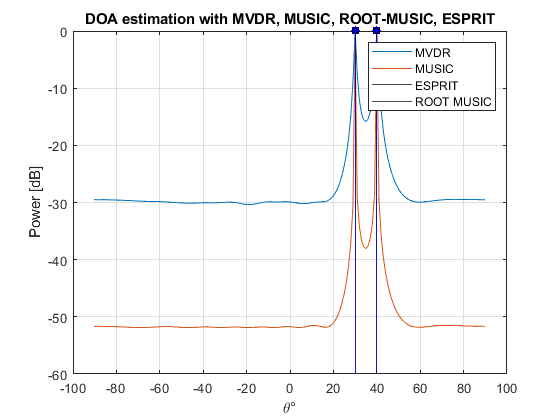

ymvdr = mvdrspatialspect(signal);
ymusic = musicspatialspect(signal);
ymvdr_dB = 20*log10(ymvdr) - max(20*log10(ymvdr));
ymusic_dB = 20*log10(ymusic) - max(20*log10(ymusic));

plot(mvdrspatialspect.ScanAngles,ymvdr_dB,musicspatialspect.ScanAngles,...
    ymusic_dB)
title('DOA estimation with MVDR, MUSIC, ROOT-MUSIC, ESPRIT')
xlabel(['\theta' char(176)])
ylabel('Power [dB]')
grid on
hold on
xline(yesprit(1),'black');
xline(yesprit(2),'black');

yesprit1 = scatter(yesprit(1),0);
yesprit1.Marker = 'square';
yesprit1.MarkerFaceColor = 'black';
yesprit1.MarkerEdgeColor = 'black';
 
yesprit2 = scatter(yesprit(2),0);
yesprit2.Marker = 'square';
yesprit2.MarkerFaceColor = 'black';
yesprit2.MarkerEdgeColor = 'black';

xline(yrootmusic(1),'blue');
xline(yrootmusic(2),'blue');

yrootmusic1 = scatter(yrootmusic(1),0);
yrootmusic1.Marker = '*';
yrootmusic1.MarkerFaceColor = 'blue';
yrootmusic1.MarkerEdgeColor = 'blue';
 
yrootmusic2 = scatter(yrootmusic(2),0);
yrootmusic2.Marker = '*';
yrootmusic2.MarkerFaceColor = 'blue';
yrootmusic2.MarkerEdgeColor = 'blue';

legend('MVDR','MUSIC','ESPRIT','ROOT MUSIC');